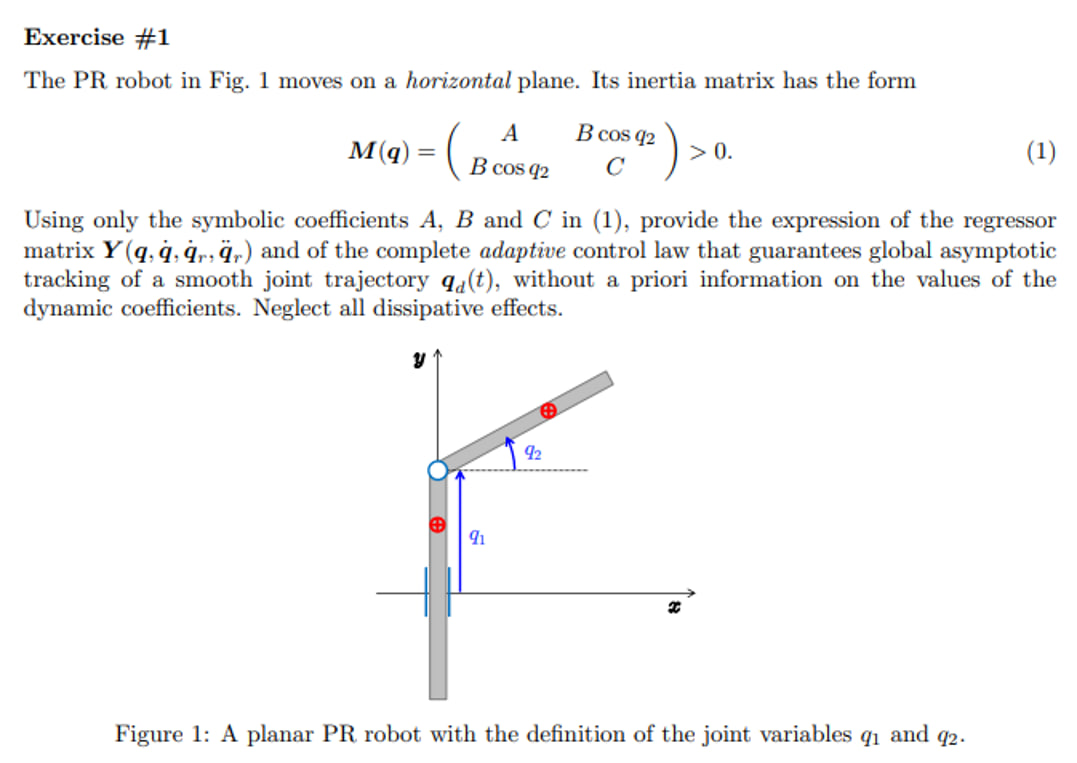

syms q1 q2 q_dot_1 q_dot_2 A B C 
M = [A B*cos(q2);
     B*cos(q2) C;];
% Coriolis and Centrifugal force
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & -B\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -B\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$